# Анализ линейной дискретной системы

Данный скрипт использует **MATLAB** и **Signal Processing Toolbox**

### Коэффициенты дискретной системы (фильтра)

Загрузим входной аудио-файл, который мы будем пропускать через фильтр, послушаем его и построим спектр:

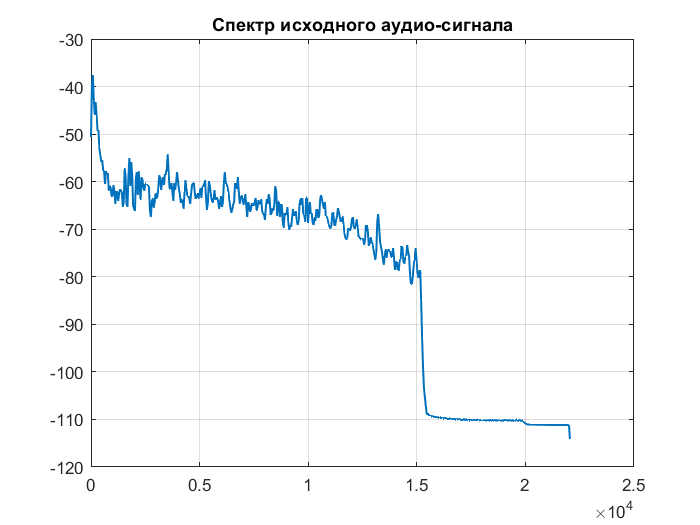

[x,fs] = audioread('energy.mp3');
% sound(x,fs)
[pxx,ff] = pwelch(x,1024,512,1024,fs);
plot(ff,10*log10(pxx),'LineWidth',1)
grid
title('Спектр исходного аудио-сигнала')

### Коэффициенты и анализ нашей системы:

Укажем коэффициенты линейной дискретной системы и оценим АЧХ и ФЧХ:

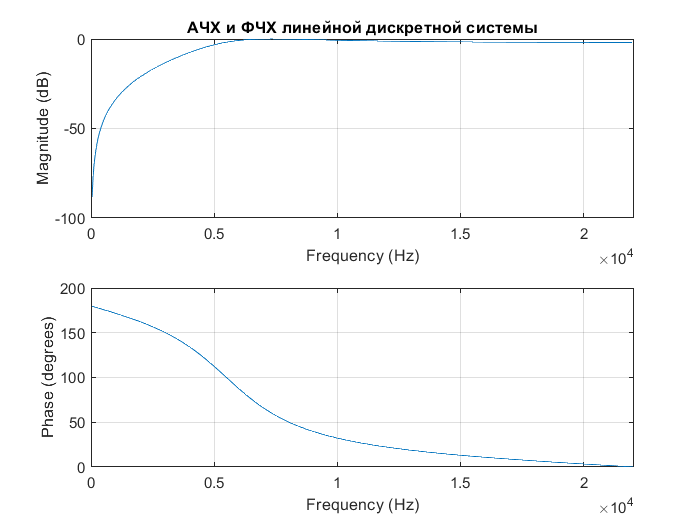

b = [0.5 -1 0.5];
a = [1 -1 0.5];
freqz(b,a,[],fs)
title('АЧХ и ФЧХ линейной дискретной системы')

Построим импульсную характеристику системы:

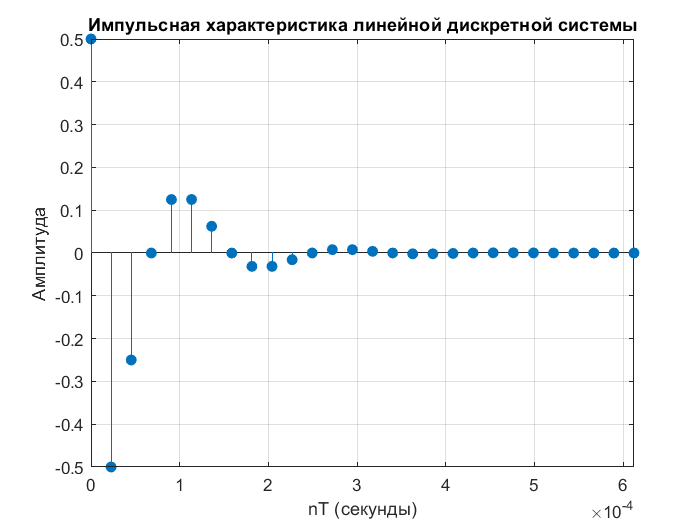

impz(b,a,[],fs)
grid
title('Импульсная характеристика линейной дискретной системы')
xlabel('nT (секунды)')
ylabel('Амплитуда')

А также нуль-полюсную диаграмму:

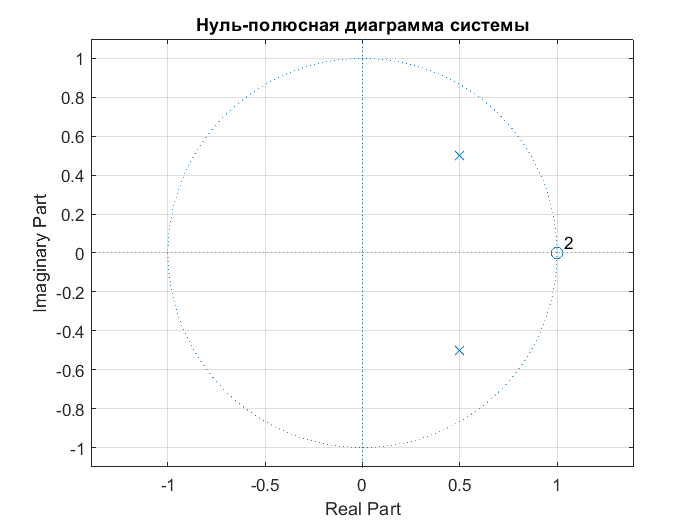

[z,p,k] = tf2zpk(b,a);
zplane(z,p,k)
title('Нуль-полюсная диаграмма системы')
grid

Проанализируем систему в **Filter Visualization Tool:**

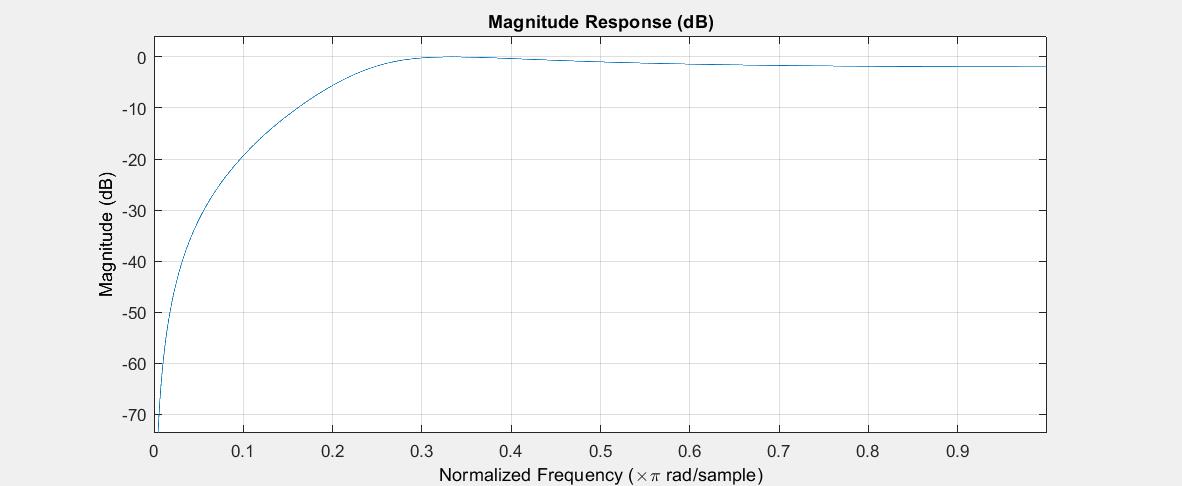

fvtool(b,a)

### Применение фильтра

Отправим коэффициенты функции filter, применим её к исходному сигналу и прослушаем результат: 

y = filter(b,a,x);
% sound(y,fs)

### Сравнение спектов входного и выходного сигналов

Наложим на исходный спектр сигнала после фильтрации:

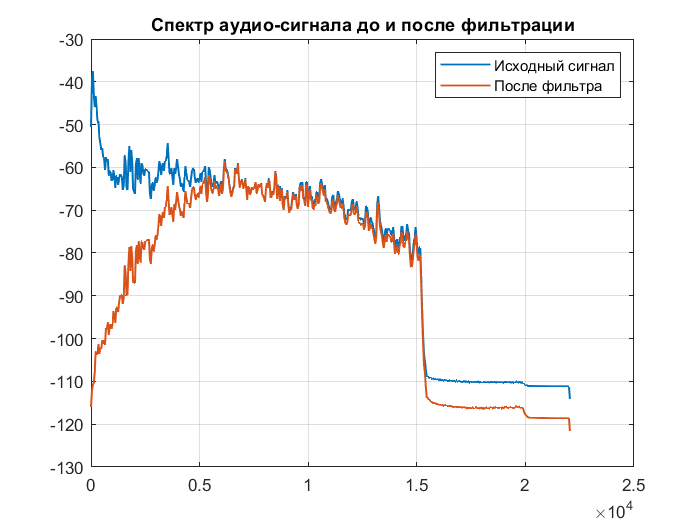

pyy = pwelch(y,1024,512,1024,fs);
plot(ff,10*log10(pxx),'LineWidth',1)
grid
hold on
plot(ff,10*log10(pyy),'LineWidth',1)
hold off
title('Спектр аудио-сигнала до и после фильтрации')
legend('Исходный сигнал','После фильтра')